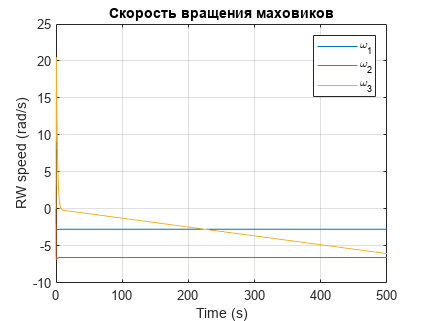

clear all
clc
global M_rw_log k_log

% === Параметры спутника ===
ms = 2.6; % масса, кг
lx = 10/100; ly = 10/100; lz = 20/100;  % размеры, м
l = [lx; ly; lz];
lsort = sort(l);
Amax = lsort(2) * lsort(3);  % максимальная поперечная площадь
lmax = l(3);
CD = 1.0;  % коэффициент сопротивления

% === Тензор инерции корпуса ===
Is = (ms/12) * [ly^2+lz^2, 0, 0;
                0, lx^2+lz^2, 0;
                0, 0, lx^2+ly^2];

% === Параметры маховиков ===
reaction_wheel_params

% === Полная инерция системы ===
m = ms + 3*mr;
I = Is + Ir1Bcg + Ir2Bcg + Ir3Bcg;
invI = inv(I);

% === Параметры ПД-регулятора ===
Kp = diag([0.5, 0.5, 0.5]);
Kd = diag([5.0, 5.0, 5.0]);
maxTorque = 0.004;  % Н·м

% === Внешние возмущения ===
M_disturb = [0;0;0];

% === Начальные условия ===
omega0 = deg2rad([1; 2; -1]);
q0 = [1; 0; 0; 0];
x0 = [omega0; q0];

% === Целевая ориентация ===
q_desired = [cosd(15/2); 0; 0; sind(15/2)];

% === Время симуляции ===
T_end = 500;

% === Инициализация логгера управляющего момента ===
M_rw_log = zeros(3, 80000);  % запас на 50 тыс. шагов
k_log = 1;

% === Запуск симуляции ===
[t_out, x_out] = ode45(@(t, x) rhs_attitude(t, x, I, invI, Kp, Kd, maxTorque, M_disturb, q_desired), [0 T_end], x0);

% === Обработка результатов ===
t = t_out';
N = length(t);
omega_hist = x_out(:,1:3)';
q_hist = x_out(:,4:7)';
q_hist = q_hist ./ vecnorm(q_hist);

M_rw_log = M_rw_log(:, 1:N);  % обрезаем лог по числу шагов
rw_speed = zeros(3, N);

% === Расчёт скорости маховиков ===
Jr = IrR(1,1);
for k = 2:N
    dt_k = t(k) - t(k-1);
    M_rw_k = M_rw_log(:, k-1);
    alpha_rw = M_rw_k / Jr;
    rw_speed(:,k) = rw_speed(:,k-1) + alpha_rw * dt_k;
end

% === Кватернионы → углы Эйлера ===
euler_hist = zeros(3, N);
for k = 1:N
    q = q_hist(:,k);
    R = quat2rotm(q');
    eul = rotm2eul(R, 'ZYX')';
    euler_hist(:,k) = rad2deg(eul);
end

% === График скорости маховиков ===
figure;
plot(t, rw_speed');
xlabel('Time (s)');
ylabel('RW speed (rad/s)');
title('Скорость вращения маховиков');
legend('\omega_1', '\omega_2', '\omega_3');
grid on;

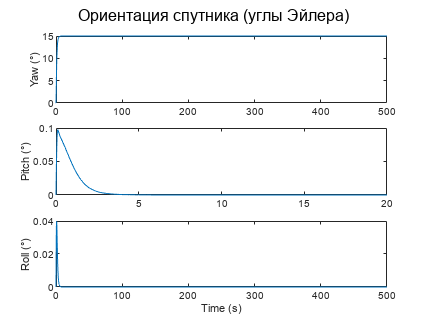


% === Графики углов Эйлера ===
figure;
subplot(3,1,1); plot(t, euler_hist(1,:)); ylabel('Yaw (°)');
subplot(3,1,2); plot(t, euler_hist(2,:)); ylabel('Pitch (°)');
subplot(3,1,3); plot(t, euler_hist(3,:)); ylabel('Roll (°)');
xlabel('Time (s)'); sgtitle('Ориентация спутника (углы Эйлера)');
subplot(3,1,2); xlim([0 20]);

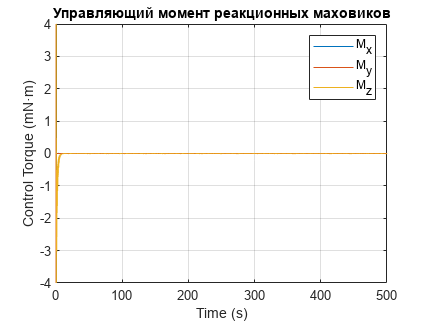


% === График управляющих моментов ===
figure;
plot(t, 1000 * M_rw_log');
xlabel('Time (s)');
ylabel('Control Torque (mN·m)');
title('Управляющий момент реакционных маховиков');
legend('M_x', 'M_y', 'M_z');
grid on;

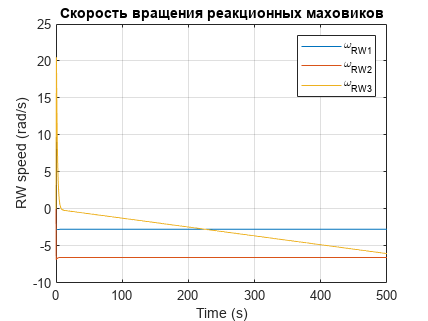


% === Повтор графика скорости маховиков ===
figure;
plot(t, rw_speed');
xlabel('Time (s)');
ylabel('RW speed (rad/s)');
title('Скорость вращения реакционных маховиков');
legend('\omega_{RW1}', '\omega_{RW2}', '\omega_{RW3}');
grid on;